## Tutorial 4: Two step optimization part one: the cell finding module

In this tutorial, we will discuss the first important step of optimizing EXTRACT's hyperparameters: the cell finding module. For this tutorial, we use a two-photon calcium imaging movie collected following the published guidelines, which is courtesy of Ben Yang -Parker Lab. See Parker, J.G., Marshall, J.D., Ahanonu, B. et al. Diametric neural ensemble dynamics in parkinsonian and dyskinetic states. Nature 557, 177–182 (2018). https://doi.org/10.1038/s41586-018-0090-6 Extended Data Fig 4 for more information on the imaging and experimental conditions.

setupEXTRACT; % add EXTRACT to the path if it is not already there

### Watching the preprocessed movie

As the first step, we watch the preprocessed movie and ensure that the motion is properly corrected and the spatial filtering does not introduce significant artifacts.

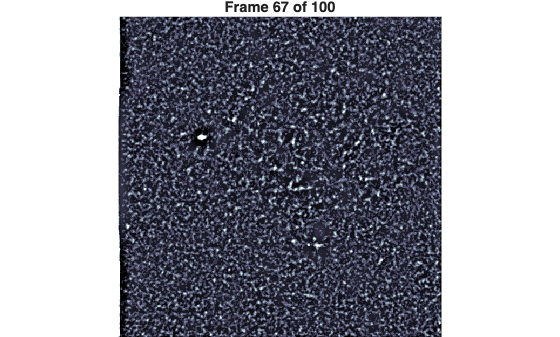

Example_1p_movie = char('/Users/johnmarshall/Documents/Analysis/miniscope_analysis/caliAliData/m328_Yiwen/day005_17_23_44_combined_ds_mc_Aligned_1000_2000.h5');

M = h5read(Example_1p_movie,'/mov');
config = get_defaults([]);
M_proc = preprocess_movie(M,config);
view_movie(M_proc(:,:,1:100))

From watching the preprocessed movie, it is rather clear that we are aiming to perform cell extraction from a rather low SNR movie, in which the cells are barely visible to the eye. Thus, cell finding module likely needs to be tweaked to account for this fact.

### Cell extraction with defaults

We start with a simple cell extraction using mainly the default parameters.

M = [Example_1p_movie ':/mov'];
config = get_defaults([]);
config.downsample_time_by = 1;
config.use_gpu = 0;
output = extractor(M,config);

19-Mar-2026 15:20:44: Signal extraction will run on 4 partitions serially... 
19-Mar-2026 15:20:44: Signal extraction on partition 4 (of 4):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.1 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.9733 
	 	 	 	 minimum magnitude: 1.3402 
	 	 	 37 cells found after a total of 51 steps... 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 32 (5 removed) 
	 	 	 End of iter # 2: # cells: 31 (1 removed) 
	 	 	 End of iter # 3: # cells: 29 (2 removed) 
	 	 	 End of iter # 4: # cells: 29 (0 removed) 
	 	 	 End of iter # 5: # cells: 29 (0 removed) 
	 	 	 End of iter # 6: # cells: 29 (0 removed) 
	 	 	 Providing baseline adjusted traces with adaptive kappa... 
	 	 	 Count: 29 cells.
19-Mar-2026 15:21:04: Signal extraction on partition 3 (of 4):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...


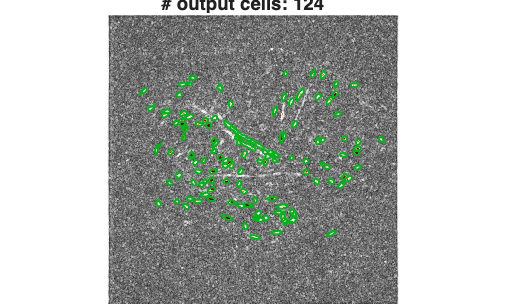

plot_output_cellmap(output,[],[],'clim_scale',[0, 0.999])

drawnow

As expected, the cell extraction with default values missed several cells. There may be several reasons, one of which is the failure of the cell finding module. To test this, we can turn off the cell refinement process and watch the cell extraction real-time as it is happening with following the code:

19-Mar-2026 15:22:37: Signal extraction will run on 4 partitions serially... 
19-Mar-2026 15:22:37: Signal extraction on partition 4 (of 4):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.1 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 0.9733 
	 	 	 	 minimum magnitude: 1.3402 
	 	 	 37 cells found after a total of 51 steps... 
	 	 	 Skipping cell refinement module...
	 	 	 Providing baseline adjusted traces with adaptive kappa... 
	 	 	 Count: 37 cells.
19-Mar-2026 15:22:54: Signal extraction on partition 3 (of 4):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 0.9675 
	 	 	 	 minimum magnitude: 1.3323 
	 	 	 42 cells found after a total of 71 steps... 
	 	 	 Skipping cell refinement module...
	 

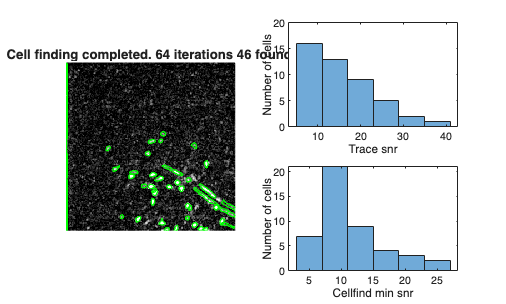

	 	 	 46 cells found after a total of 64 steps... 
	 	 	 Skipping cell refinement module...
	 	 	 Providing baseline adjusted traces with adaptive kappa... 
	 	 	 Count: 46 cells.
19-Mar-2026 15:23:36: Total of 170 cells are found.
19-Mar-2026 15:23:36: Removing duplicate cells...
19-Mar-2026 15:23:36: 155 cells were retained after removing duplicates.
19-Mar-2026 15:23:36: All done with EXTRACT! 


config.max_iter = 0;
config.visualize_cellfinding = 1;
output = extractor(M,config);

Indeed, as can be seen above, cell finding module is missing several low SNR cells that should have been identified.

### Optimizing the cell finding module

To optimize the cell finding module, we will first note that the earlier run had shown an early cutoff for the trace snr values, indicating that more cells might have been found in lower SNR values. Second, the cellfind min snr value was centered around 5 (often should be ~10-100s), a rather low value. Thus, we first pick very low values for both parameters. 

Next, since our main concern is being able to identify cells, we can also decrease the cutoff value for the spatial lowpass filter. This will allow more smoothing of the movie used for the cell finding purposes only.

19-Mar-2026 15:24:59: Signal extraction will run on 4 partitions serially... 
19-Mar-2026 15:24:59: Signal extraction on partition 4 (of 4):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.1 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 0.3552 
	 	 	 	 minimum magnitude: 0.1339 
			 Step #100, found 86 cells... 
	 	 	 110 cells found after a total of 160 steps... 
	 	 	 Skipping cell refinement module...
	 	 	 Re-estimating T for all frames... 
	 	 	 Count: 110 cells.
19-Mar-2026 15:25:23: Signal extraction on partition 3 (of 4):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 0.3550 
	 	 	 	 minimum magnitude: 0.1338 
			 Step #100, found 91 cells... 
			 Step #200, found 144 cells... 
	 	 	 145 ce

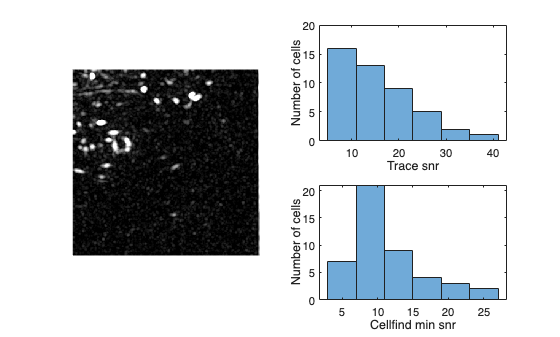

	 	 	 152 cells found after a total of 197 steps... 
	 	 	 Skipping cell refinement module...
	 	 	 Re-estimating T for all frames... 
	 	 	 Count: 152 cells.
19-Mar-2026 15:26:40: Total of 520 cells are found.
19-Mar-2026 15:26:40: Removing duplicate cells...
19-Mar-2026 15:26:41: 484 cells were retained after removing duplicates.
19-Mar-2026 15:26:41: All done with EXTRACT! 


M = [Example_1p_movie ':/mov'];
config = get_defaults([]);
config.downsample_time_by = 4;
config.spatial_lowpass_cutoff = 1;
config.use_gpu = 0;
config.max_iter = 0;
config.visualize_cellfinding = 1;
config.cellfind_min_snr = 0;
config.thresholds.T_min_snr = 3.5;
output = extractor(M,config);

And voila! We have achieved a satisfactory cell finding process, where almost all cells (but also some garbage) are found. The next tutorial will discuss how to optimize the cell refinement module, which primarily aims to cull away the false-positive candidates.